# First Order Ordinary Linear Systems

In this section, we try to solve $\mathbf{A}_1\mathbf{u}'(x)+\mathbf{A}_2\mathbf{u}(x)=\mathbf{f}(x)$ for $x\in[a,b]$ w.r.t Dirichlet boundary conditions $\mathbf{u}(x)=\mathbf{g}(x)$ for $x\in\{a,b\}$ where $\mathbf{A}_i\in\mathbb{R}^{m\times m}$ and $\mathbf{u},\mathbf{f},\mathbf{g}\in\mathbb{R}^{m\times 1}$. For ellpticity, we require $\mathrm{det}(\mathbf{A}_1)\neq0$. We approximate the solution with $C^0$ Lagrange elment $\mathrm{CG}_q$ where we first try $q=1$(linear elements). The degrees of freedom are given by evaluating the basis at both ends of the interval. In element $K$ where $K=[v^K_1,v^K_2]$, the nodal bases are given by


$$\phi_1^K(x)\ =\ \frac{v^K_2-x}{l^K},$$



$$\phi_2^K(x)\ =\ \frac{x-v^K_1}{l^K},$$


where $l^K=v^K_2-v^K_1$. The solution ansatz is given as


$$\mathbf{u}(x)\approx\mathbf{u_C}(x)=\mathbf{C}\mathbf{\phi}(x)=\sum^n_{i=1}\mathbf{c}_i \cdot\phi_i(x),$$


where $\mathbf{c}_i$ is the $i_{th}$ column of $\mathbf{C}\in\mathbb{R}^{m\times n}$,  $\phi_i(x)$ is the global basis corresponding to the $i_{th}$ global degree of freedom (resp. the $i_{th}$ global vertex $v_i$ forming the discretized mesh). $\phi_i(x)$ for $i=1,n$ corresponds to the two boundary nodes $v_1=a$ and $v_n=b$.

We start by forming a 1D mesh $\mathcal{M}=\{K_i\}_{i=1}^{n-1}$ for the interval $\Omega=[a,b]$ and stores the global vertices in a 1D vector $\mathbf{v}=[v_1,\cdots,v_n]$ such that $K_i=[v_i\  ,\ v_{i+1}]$ for $i=1\cdots (n-1)$. 

% Sloution Benchmark
u  = @(x) [sin(x) ;  cos(x)] ;
Du = @(x) [cos(x) ; -sin(x)] ; 

% System Settings
m  = 2            ;  % number of dependent variables
ab = [ 0 , pi ]   ;  % ab = [ a , b ] domain

global A1 A0 f g 
A1 = @(x) [cos(x), -sin(x); sin(x), cos(x)] ;
A0 = @(x) [cos(x), -sin(x); sin(x), cos(x)] ;
f  = @(x) [1 ; 1] ;
g  = @(x) u(x)    ;

% Discretization
global v 
n = 2000 ;                         % n global vertices
v = linspace(ab(1), ab(2), n) ;    % store the global vertices

We now try to evaluate the residuals. For a given point $x\in K_i$ with a local-to-global map $\iota_{K_i}(j)=i+(j-1)$ where $j=1,2$ we can evaluate the interior residuals

$R_{\Omega}(x)=\mathbf{A}_1\mathbf{u_C}'(x)+\mathbf{A}_2\mathbf{u_C}(x)-\mathbf{f}(x)
$,

namely,

$R_{\Omega}(x)=

\left[\matrix{\ 

(\phi_1^K)'\mathbf{A}_1+\phi_1^K\mathbf{A}_0

&,&  

(\phi_2^K)'\mathbf{A}_1+\phi_2^K\mathbf{A}_0

\    } \right]

\left[\matrix{ \mathbf{c}_{\iota_K(1)}  \cr  \mathbf{c}_{\iota_K(2)} } \right]-\mathbf{f}(x)$.

Similar for the boundary residuals with weights specified by the diagonal matrix $\Lambda\in\mathbb{R}^{m\times m}$

$R_{\Gamma}(x)=\Lambda[\mathbf{u_C}(x)-\mathbf{g}(x)]
$,

there is 


$$R_{\Gamma}(x)=\left[\matrix{\ \phi_1^K(x)\Lambda &,&  \phi_2^K(x)\Lambda\    } \right]\left[\matrix{ \mathbf{c}_{\iota_K(1)}  \cr  \mathbf{c}_{\iota_K(2)} } \right]-\Lambda\mathbf{g}(x)$$


Note if we write 

$\mathbf{B}^K_\Omega(x) = \left[\matrix{ (\phi_1^K)'\mathbf{A}_1+\phi_1^K\mathbf{A}_0 &,&  (\phi_2^K)'\mathbf{A}_1+\phi_2^K\mathbf{A}_0\    } \right]\in\mathbb{R}^{m\times 2m}$ for $x\in\mathrm{int}(\Omega)$, 

$\mathbf{B}^K_\Gamma(x) = \left[\matrix{\ \phi_1^K(x)\Lambda &,&  \phi_2^K(x)\Lambda\    } \right]\in\mathbb{R}^{m\times 2m}$ for $x\in \Gamma=\partial\Omega$, 

a single point $x$ will generate $m$ lines in the final assembled system $\mathbf{B}\mathbf{c}=\mathbf{d}$ where 

$\mathbf{B}=\left[\matrix{ \mathbf{B}_\Omega  \cr  \mathbf{B}_\Gamma} \right]$ , $\mathbf{c}=\mathrm{vec}(\mathbf{C})=\left[\matrix{ \mathbf{c}_1  \cr  \vdots\cr\mathbf{c}_n} \right]$ , $\mathbf{d}=\left[\matrix{ \mathbf{d}_\Omega  \cr  \mathbf{d}_\Gamma} \right]$

and if we define slice $\mathbf{s}(i)=im-m+1:im$, there is

$\mathbf{B}_{\Omega}(\ \mathbf{s}(i)\ ,\  [\mathbf{s}\circ\iota_K(1) \ ,\  \mathbf{s}\circ\iota_K(2)]\ ) := \mathbf{B}^K_\Omega(x_i)$,

$\mathbf{B}_{\Gamma}(\ \mathbf{s}(i)\ ,\  [\mathbf{s}\circ\iota_K(1) \ ,\  \mathbf{s}\circ\iota_K(2)]\ ) := \mathbf{B}^K_\Gamma(\hat{x}_i)$,

and 

$\mathbf{d}_{\Omega}(\ \mathbf{s}(i)\  ) := \mathbf{f}(x_i)$,

$\mathbf{d}_{\Gamma}(\ \mathbf{s}(i)\  ) := \Lambda\mathbf{g}(\hat{x}_i)$,

for sets of selected points $\{{x}_i\}_{i=1}^{N_{\Omega}}\subset \Omega$ and $\{{\hat{x}}_i\}_{i=1}^{ N_{\Gamma} } \subset \Gamma$, $N=N_{\Omega}+N_{\Gamma}$.

% Points Selection
rng(42) ;  % random seed
interior_points = linspace(ab(1), ab(2), 2*n-1) ; % interior points
boundary_points = sort(datasample(ab, 10))      ; % boundary points

N_Omega = length(interior_points) ;  % number of interior points
N_Gamma = length(boundary_points) ;  % number of boundary points
Lambda = diag(100*ones(1,m)) ;       % square(weights) for BC

B_Omega = [] ; B_Gamma = [] ;
d_Omega = [] ; d_Gamma = [] ;

for i = 1:N_Omega
    x = interior_points(i)    ;
    eleID = findElement(x, v) ;
    
    iota1 = local_to_global(1, eleID) ;
    iota2 = local_to_global(2, eleID) ;
    B_Omega(slice(i, m) , [slice(iota1, m), slice(iota2, m)]) = B_Omega_loc(x, v) ;
    d_Omega(slice(i, m), 1) = f(x) ;
end

for i = 1:N_Gamma
    x = boundary_points(i)    ;
    eleID = findElement(x, v) ;

    iota1 = local_to_global(1, eleID) ;
    iota2 = local_to_global(2, eleID) ;
    B_Gamma(slice(i, m) , [slice(iota1, m), slice(iota2, m)]) = B_Gamma_loc(x, v, Lambda) ;
    d_Gamma(slice(i, m), 1) = Lambda*g(x) ;
end

B = [B_Omega ; B_Gamma] ;
d = [d_Omega ; d_Gamma] ;

We first solve the assembled matrix directly

c = lsqr(B, d, [], 10000)

lsqr 在解的 迭代 2009 处收敛，并且相对残差为 8.7e-05。


c =    -0.0000
    1.0000
    0.0016
    1.0000
    0.0031
    1.0000
    0.0047
    1.0000
    0.0063
    1.0000


C = reshape(c, m, n) ; 

C =    -0.0000    0.0016    0.0031    0.0047    0.0063    0.0079    0.0094    0.0110    0.0126    0.0141    0.0157    0.0173    0.0189    0.0204    0.0220    0.0236    0.0251    0.0267    0.0283    0.0299    0.0314    0.0330    0.0346    0.0361    0.0377    0.0393    0.0408    0.0424    0.0440    0.0456    0.0471    0.0487    0.0503    0.0518    0.0534    0.0550    0.0565    0.0581    0.0597    0.0613    0.0628    0.0644    0.0660    0.0675    0.0691    0.0707    0.0722    0.0738    0.0754    0.0769
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9997    0.9997    0.9997    0.9996    0.9996    0.9995    0.9995    0.9994    0.9994    0.9993    0.9992    0.9992    0.9991    0.9991    0.9990    0.9989    0.9988    0.9988    0.9987    0.9986    0.9985    0.9984    0.9983    0.9982    0.9981    0.9981    0.9980    0.9978    0.9977    0.9976    0.9975    0.9974    0.9973    0.9972    0

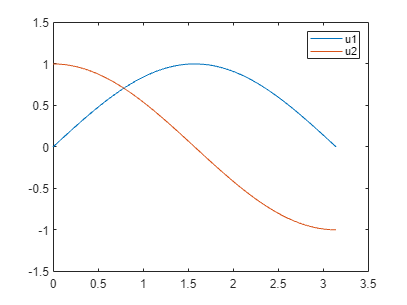


xs = linspace(ab(1), ab(2), 100) ;
us_fit = evaluate_LSFEM(xs, C)   ;

% Plot the solution
plot(xs, us_fit(1,:), xs, us_fit(2,:)) ;
legend("u1","u2") ;

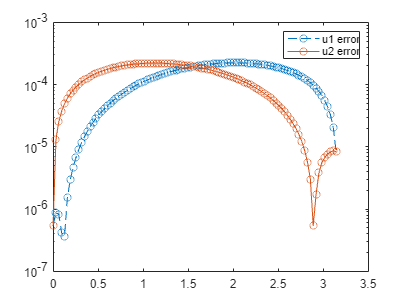


% Plot the error
abs_error = abs(us_fit - u(xs)) ;
semilogy(xs, abs_error(1,:), '--o', xs, abs_error(2,:), '-o') ;
legend("u1 error","u2 error") ;

function eleID = findElement(x, v)
    n = length(v) ;
    eleID = min(sum(v <= x), n-1) ; 
end


function vID_glb = local_to_global(vID_loc, eleID)
    vID_glb = eleID + vID_loc - 1 ;
end


function ss = slice(i, m)
    ss = (i-1)*m+1 : i*m ;
end


function B_Omega_loc = B_Omega_loc(x, v)
    global A1 A0
    eleID = findElement(x, v) ;
    v1_loc = v(eleID)   ;
    v2_loc = v(eleID+1) ;
    l_loc  = v2_loc - v1_loc ;

    phi1_loc = (v2_loc - x)/l_loc ;
    phi2_loc = (x - v1_loc)/l_loc ;
    Dphi1_loc = - 1/l_loc ;
    Dphi2_loc = 1/l_loc   ;

    B1_loc = Dphi1_loc * A1(x) + phi1_loc * A0(x) ;
    B2_loc = Dphi2_loc * A1(x) + phi2_loc * A0(x) ;

    B_Omega_loc = [ B1_loc , B2_loc ] ;
end


function B_Gamma_loc = B_Gamma_loc(x, v, Lambda)
    eleID = findElement(x, v) ;
    v1_loc = v(eleID)   ;
    v2_loc = v(eleID+1) ;
    l_loc  = v2_loc - v1_loc ;

    phi1_loc = (v2_loc - x)/l_loc ;
    phi2_loc = (x - v1_loc)/l_loc ;

    B1_loc = phi1_loc * Lambda ;
    B2_loc = phi2_loc * Lambda ;

    B_Gamma_loc = [ B1_loc , B2_loc ] ;
end


function u_fit = evaluate_LSFEM_elewise(x, C)
    global v 
    eleID = findElement(x, v) ;
    v1_loc = v(eleID)   ;
    v2_loc = v(eleID+1) ;
    l_loc  = v2_loc - v1_loc ;

    phi1_loc = (v2_loc - x)/l_loc ;
    phi2_loc = (x - v1_loc)/l_loc ;

    v1ID_glb  = local_to_global(1, eleID) ;
    v2ID_glb  = local_to_global(2, eleID) ;

    u_fit = C(:,v1ID_glb) * phi1_loc + C(:,v2ID_glb) * phi2_loc ;
end


function u_fit = evaluate_LSFEM(xs, C)
    global v 
    u_fit = [] ;
    for x = xs 
        u_fit = [u_fit, evaluate_LSFEM_elewise(x, C)] ;
    end
end
